# MATLAB for Business Analytics: Forecasting, Optimization, and AI Agents

You will not need to write algorithms from scratch today.

Every technique here is a single MATLAB function or app - your job is to interpret what it tells you about the business, the same way you would read output from Excel, Power BI, or SPSS.

We follow one fictional retailer, **Brighten Up Mart**, through three connected decisions that any retail, logistics, or supply-chain manager faces every month.

- **Part 1 - Machine Learning for Forecasting:** how much will customers buy next quarter?

- **Part 2 - Transportation Optimization:** given that demand, what is the cheapest way to ship inventory to stores?

- **Part 3 - AI Agentics for Data Analytics and Dashboard Intelligence:** how do we turn all of this into a dashboard - and an assistant - that busy executives can actually use

## The Business Scenario

Brighten Up Mart is a Thai retail chain with three regional distribution centers and five stores.

Every month, the management team has to answer three questions: *How much will we sell?*, *How do we distribute stock at the lowest cost?*, and *How do we get answers fast, without waiting for an analyst?*

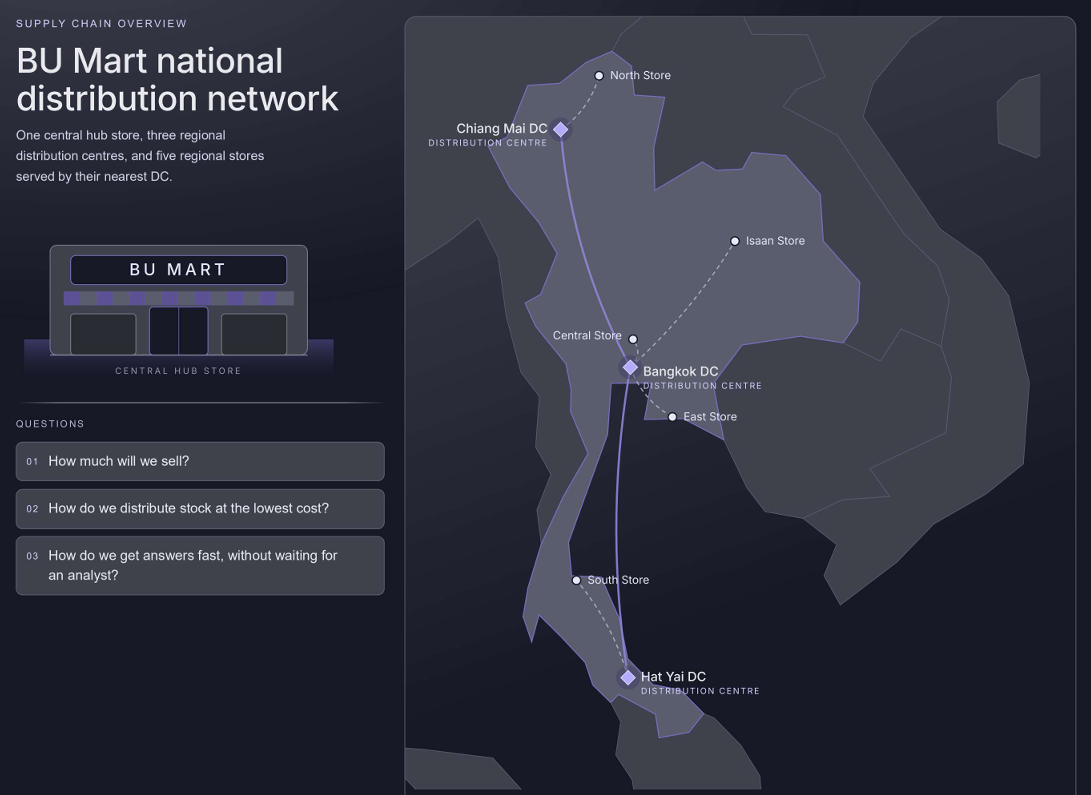

We start by loading four years of monthly sales history, together with the marketing budget spent each month - a common early-warning signal for demand.

% Import data from text file
BUS = readtimetable("data/BrightenUpMartSales.csv", "RowTimes", ...

BUS = 48×2 timetable
    01-Jan-2022    560     31
    01-Feb-2022    590     47
    01-Mar-2022    543     36
    01-Apr-2022    807    117
    01-May-2022    699     52
    01-Jun-2022    722     41
    01-Jul-2022    721     40
    01-Aug-2022    615     28
    01-Sep-2022    601     38
    01-Oct-2022    588     40
    01-Nov-2022    791    122
    01-Dec-2022    800    125
    01-Jan-2023    579     37
    01-Feb-2023    558     24


    "Month");



BUS: 48×2 timetable

Row Times:

    Month: datetime

Variables:

    Sales: double
    MarketingSpend: double

Statistics for applicable variables and row times:

                      NumMissing          Min              Median               Max               Mean                Std      

    Month                 0           01-Jan-2022        16-Dec-2023        01-Dec-2025        16-Dec-2023        10230:30:19  
    Sales                 0                   543                723                933           723.3958           102.1165  
    MarketingSpend        0                    21                 41                129            58.8958            35.3422  



% Display results
BUS

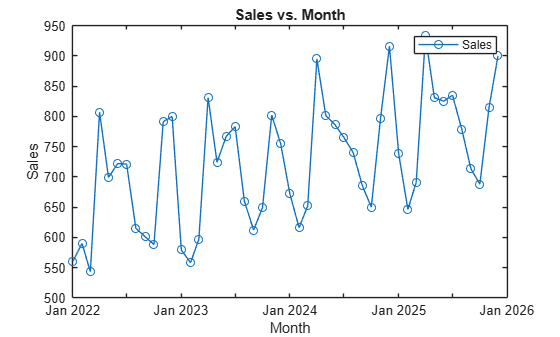

summary(BUS)

## A First Look at the Data

Before modeling anything, always plot the raw series.

Look for the two patterns that matter most to a forecaster: an upward *trend* as the chain grows, and a repeating *seasonal* pattern tied to promotions such as Songkran in April and the year-end sale.

### Plot unit sales in time

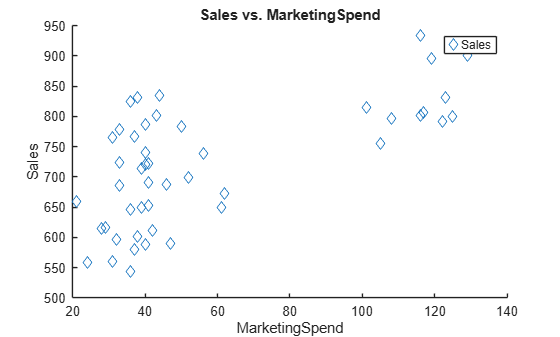

% Create plot of BUS.Month and BUS.Sales
s = plot(BUS,"Month","Sales","Marker","o","DisplayName","Sales");


% Add xlabel, ylabel, title, and legend
xlabel("Month")
ylabel("Sales")
title("Sales vs. Month")
legend

### Try to find some correlation between data with Scatter plot

% Create scatter of BUS.MarketingSpend and BUS.Sales
sm = scatter(BUS,"MarketingSpend","Sales","Marker","diamond","DisplayName","Sales");

BUS_Features = 36×5 table
     1    800    560     37    579
     2    579    590     24    558
     3    558    543     32    597
     4    597    807    123    831
     5    831    699     33    724
     6    724    722     37    767
     7    767    721     50    783
     8    783    615     21    660
     9    660    601     42    612
    10    612    588     61    649
    11    649    791    116    802
    12    802    800    105    755
     1    755    579     62    672
     2    672    558     29    616



% Add xlabel, ylabel, title, and legend
xlabel("MarketingSpend")
ylabel("Sales")
title("Sales vs. MarketingSpend")
legend

## Part 1: Machine Learning for Forecasting

Traditional forecasting rules ("this month equals the same month last year, plus a bit of growth") are simple but blind to anything unusual, such as a bigger-than-usual marketing push.

Machine learning takes a different approach: show the computer many historical examples - the month of the year, last month's sales, the same month a year ago, and the marketing budget - and let it learn the relationship on its own.

It is the same underlying idea used in product recommendations and credit-risk scoring, applied here to demand instead.

### Turning History into Learning Examples

A machine learning model needs the problem framed as *features in, sales out*.

We build one row per month containing the calendar month, last month's sales, the same month one year prior, and the marketing spend planned for that month - then hold out the most recent six months to test the model honestly, on data it has never seen.

% Import data from text file
BUS_Features = readtable("data/BrightenUpMartSales_Features.csv");

forecastTbl = 6×3 table
    01-Jan-2026    792     27
    01-Feb-2026    702     35
    01-Mar-2026    732     44
    01-Apr-2026    952    111
    01-May-2026    865     24
    01-Jun-2026    849     25



% Display results
BUS_Features

% lag1 = [NaN; BUS.Sales(1:end-1)];
% lag12 = [NaN(12,1); BUS.Sales(1:end-12)];
% featTbl = table(month(BUS.Month), lag1, lag12, BUS.MarketingSpend, BUS.Sales, 'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend','Sales'});
% featTbl = featTbl(13:end,:);
% featTbl(1:6,:)

% clear lag1 lag12 featTbl 

### Training the Model by Regression Learner App

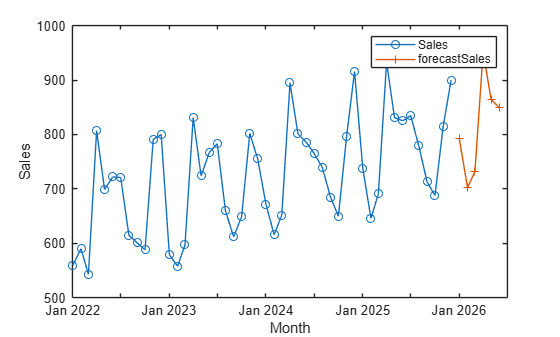

load data/Rblin.mat

### Forecasting

With the approach validated, we retrain on the full history and roll the model forward six months, feeding each prediction back in as next month's "last month" value.

The marketing team has already shared its budget plan for the period, including a larger Songkran push in April - this lets the model anticipate the spike instead of being surprised by it.

targetm = 6; % define the duration of forecasting

totalDemand = 952

focusmkt = 4; % define the month that will boost the marketing spend

totalSupply = 981


monthIdx = 1:targetm; % create index from defined target m
futureDates = BUS.Month(end) + calmonths(monthIdx)'; % create futureDates for forecasting


demand = 

    252
    207
    172
    161
    160


% create randomize market spend with a spike in the focus month
rng(7) % fix the random seed so every run reproduces the same numbers
plannedSpend = poissrnd(mode(BUS.MarketingSpend), [targetm,1]);
plannedSpend(focusmkt) = round(mode(BUS.MarketingSpend) + 2*std(BUS.MarketingSpend));
forecastSales = zeros(targetm,1); % allocate array for forecastSales

supply = 

    462
    284
    235


lag1cur = BUS.Sales(end); % 

cost = 

    2000     600     900    2500    1500
     700    2000    2300    3700    1800
    3700    2500    2600     700    2800


for h = monthIdx

costTbl = 3×5 table
    2000     600     900    2500    1500
     700    2000    2300    3700    1800
    3700    2500    2600     700    2800


    row = table(month(futureDates(h)), lag1cur, BUS.Sales(end-12+h), plannedSpend(h), 'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend'});
    forecastSales(h) = RbLin.predictFcn(row);
    lag1cur = forecastSales(h);
end
forecastTbl = table(futureDates, round(forecastSales), plannedSpend, 'VariableNames', {'Month','ForecastSales','PlannedMarketingSpend'})

### Plotting the Forecast

The forecast picks up right where history ends, and clearly shows the expected April demand spike from the planned promotion - exactly the kind of signal that feeds into Part 2.

figure


  OptimizationProblem : 

	Solve for:
       ship

	minimize :
       2000*ship(1, 1) + 700*ship(2, 1) + 3700*ship(3, 1) + 600*ship(1, 2) + 2000*ship(2, 2) + 2500*ship(3, 2) + 900*ship(1, 3) + 2300*ship(2, 3) + 2600*ship(3, 3) + 2500*ship(1, 4) + 3700*ship(2, 4) + 700*ship(3, 4) + 1500*ship(1, 5) + 1800*ship(2, 5) + 2800*ship(3, 5)


	subject to constraint1:
       ship(1, 1) + ship(1, 2) + ship(1, 3) + ship(1, 4) + ship(1, 5) <= 462
       ship(2, 1) + ship(2, 2) + ship(2, 3) + ship(2, 4) + ship(2, 5) <= 284
       ship(3, 1) + ship(3, 2) + ship(3, 3) + ship(3, 4) + ship(3, 5) <= 235

	subject to constraint2:
       ship(1, 1) + ship(2, 1) + ship(3, 1) == 252
       ship(1, 2) + ship(2, 2) + ship(3, 2) == 207
       ship(1, 3) + ship(2, 3) + ship(3, 3) == 172
       ship(1, 4) + ship(2, 4) + ship(3, 4) == 161
       ship(1, 5) + ship(2, 5)

% Create plot of BUS.Month and BUS.Sales
plot(BUS,"Month","Sales","Marker","o","DisplayName","Sales");



Solving problem using linprog.

Optimal solution found.



hold on
% Create plot of futureDates and forecastSales
plot(futureDates,forecastSales,"Marker","+","DisplayName","forecastSales");

solution = struct with fields:
    ship: [3×5 double]


hold off

reasonSolverStopped =     OptimalSolution


objectiveValue = 876200

legend

## Part 2: Transportation Optimization

Forecasting tells us Brighten Up Mart needs to move about 948 units in April.

The next business question is purely operational: given three distribution centers with limited capacity and five stores that must each receive their share, which shipping routes should we use to meet every store's demand at the lowest possible total shipping cost?

This is the classic *transportation problem*, and it is a perfect example of business **optimization**: instead of trying options by hand in a spreadsheet, we let MATLAB search every feasible shipping plan and return the mathematically cheapest one.

### Setting Up the Distribution Network

Each distribution center (DC) has a maximum monthly capacity, each store has a demand it must receive in full, and shipping a unit costs a different amount on every route depending on distance.

dcNames = {'Bangkok DC','Chiang Mai DC','Hat Yai DC'};

ans = "April"

storeNames = {'North Store','Central Store','East Store','South Store','Isaan Store'};

shipTbl = 3×5 table
      0    207    172      0    83
    252      0      0      0    32
      0      0      0    161    45


totalCost = 876200

% aprilIdx = find(month(forecastTbl.Month) == 4, 1);
% totalDemand = round(forecastTbl.ForecastSales(aprilIdx))
totalDemand = round(forecastTbl.ForecastSales(focusmkt))
totalSupply = ceil(totalDemand*1.03)
storeShare = [0.265 0.217 0.181 0.169 0.168];
demand = round(totalDemand*storeShare)';
demand(end) = demand(end) + (totalDemand - sum(demand));
demand

dcShare = [0.47 0.29 0.24];
supply = round(totalSupply*dcShare)';
supply(1) = supply(1) + (totalSupply - sum(supply));
supply
cost = 1e2*[20 6 9 25 15; 7 20 23 37 18; 37 25 26 7 28]
costTbl = array2table(cost, 'VariableNames', storeNames, 'RowNames', dcNames)

### Solving for the Least-Cost Shipping Plan by Optimize Task

Optimize Task lets us describe the decision in business terms: choose how many units to ship on each route so that no DC ships more than its capacity, every store's demand is fully met, and total shipping cost is as low as possible.

MATLAB hands this off to a linear-programming solver, which is guaranteed to find the mathematically optimal plan - not just a good one.

% Create optimization variables
ship2 = optimvar("ship",3,5,"LowerBound",0);

savings = 1049100


% Set initial starting point for the solver
initialPoint.ship = zeros(size(ship2));

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = sum(sum(cost.*ship2));

% Define problem constraints
problem.Constraints.constraint1 = sum(ship2,2) <= supply;
problem.Constraints.constraint2 = sum(ship2,1)' == demand;

% Display problem information
show(problem);

% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint);

% Display results
solution
reasonSolverStopped
objectiveValue

% Clear temporary variables
clearvars ship2 initialPoint reasonSolverStopped objectiveValue

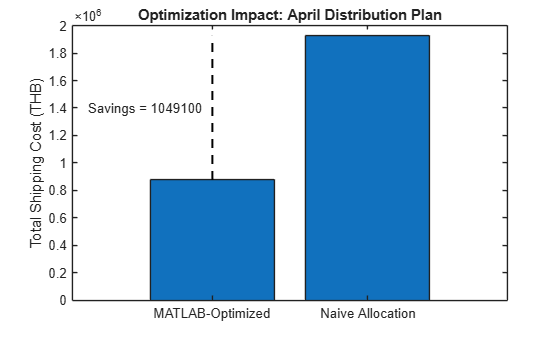

string(month(forecastTbl.Month(focusmkt),'name'))

shipTbl = array2table(round(solution.ship), 'VariableNames', storeNames, 'RowNames', dcNames)
totalCost = sum(sum(cost .* solution.ship))

### How Much Did Optimization Save?

To show the value of optimization, we compare it against a common real-world habit: allocating stock first-come, first-served, store by store, without considering cost at all.

remaining = supply;
alloc = zeros(3,5);
for j = 1:5
    d = demand(j);
    for i = 1:3
        take = min(remaining(i), d);
        alloc(i,j) = take;
        remaining(i) = remaining(i) - take;
        d = d - take;
        if d <= 0
            break
        end
    end
end
naiveCost = sum(sum(cost.*alloc));
savings = naiveCost - totalCost
bar(categorical({'Naive Allocation','MATLAB-Optimized'}), [naiveCost totalCost])

% Plot line from top of MATLAB-Optimized bar up to naive allocation value and annotate savings
% Get bar handles and heights
h = gca;
bh = findobj(h.Children,'Type','Bar');
% bh order: bars plotted last appear first; ensure mapping by categories
% Extract heights in correct category order: [Naive, MATLAB-Optimized]
heights = [];
for k = 1:length(bh)
    heights = [heights; bh(k).YData(:)']; %#ok<AGROW>
end
% Sum across groups if grouped bars; handle both grouped and single-group cases
if size(heights,1) > 1
    barVals = heights(:,1)'; % first (and only) group column
else
    barVals = heights(1,:);
end
naiveVal = barVals(1);
optVal = barVals(2);

% X positions of bars
xt = 1:2;
xOpt = xt(1);

% Draw vertical line at top of optimized bar up to naive value
yOptTop = optVal;
yNaive = naiveVal;
line([xOpt xOpt],[yOptTop yNaive],'Color','k','LineWidth',1.5,'LineStyle','--');

% Draw horizontal cap at naive value
line([xOpt-0.15 xOpt+0.15],[yNaive yNaive],'Color','k','LineWidth',1.5);

% Display savings as text near the line midpoint
savingsVal = savings;
midY = (yOptTop + yNaive)/2;
text(xOpt - 0.8, midY, sprintf('Savings = %d', round(savingsVal)), 'VerticalAlignment','middle');

% Adjust y-limits if necessary to ensure line is visible
yl = ylim;
if yNaive > yl(2)
    ylim([yl(1) yNaive*1.05]);
end
ylabel('Total Shipping Cost (THB)')
title("Optimization Impact: " + string(month(forecastTbl.Month(focusmkt),'name')) + " Distribution Plan")

Optimization saves BrightMart roughly 1M THB on this single month's shipment simply by choosing routes more intelligently, with no change to demand, supply, or prices.

## Part 3: AI Agentics for Data Analytics and Dashboard Intelligence

A forecast and an optimal shipping plan are only useful if the right people see them in time to act.

This final part covers two layers of *Business Intelligence*: a visual **dashboard** that summarizes everything at a glance, and an early look at **AI agents** - software that can take a plain-language business question and route it to the right analysis automatically, the idea behind AI copilots now appearing inside tools like Power BI and Tableau.

open BrightenUpMartDashboardApp.mlapp